# lora sim script

## lora parameters

%clear;
SF=7; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
numSym=round(50000/SF);
% numSym=840;

randomData=true;
%channel
perfectChannel=false;%no  awgn
maxDopplerShift=0;%0.45*Fs/(2^SF);%shift has to be less than 0.5*Fs/(2^SF) to have no impact
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=5; %signal to noise ratio in dB
%loops
nLoops=20;
loopSNR=true;
SNRstepsize=2;
loopDoppler=false;
dopplerStepsize=0.1e3;

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=10;%generate symbols with certain value
    messageBits=transpose(repmat(dec2bin(symbol,SF)-'0',1,numSym));% -'0' to convert binary string to vector
end
%generate lora signal
[loraSignal,decimalSymbols]=generateLoraSignal(messageBits,SF,numSym);
decimalSymbols

decimalSymbols =     36    76   123    68     3    85    50    33    60    33    83    76   108    91    88    52    93    37   110   125    58    55    88   121    20   126    31    89    57   123    56    91   102    40   107    21    99    95    76    95    11    46    69     3   107    73    98   124    85    51


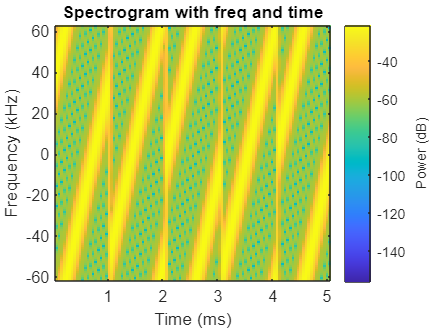

if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    % figure
    % spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    % title('Spectrogram with freq index and samples')
end

## channel & rx

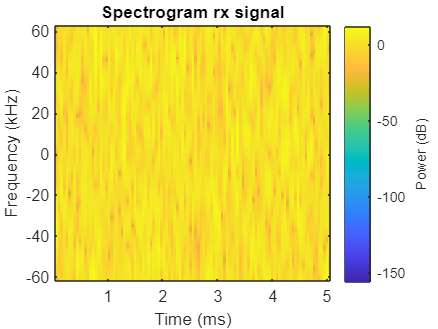

%channel
for counter=1:nLoops


    symbolDuration=(2^SF)/Fs;

    t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
    
    if flatDoppler
        freqShift=maxDopplerShift;
    else
        freqShift=linspace(dopplerShift,-dopplerShift,length(t));
    end
    dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    if perfectChannel% use maxDopplerShift = 0 for truly perfect channel
        rxSignal = loraSignal.* (dopplerEffect);
    
    else
        if loopSNR
            rxSignal=(awgn(loraSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(loraSignal,maxSNR,'measured'));
        end
        %snr
    end

    if (plotSpectrogram && counter==nLoops)
        %spectroram of first 5 symbols
        figure
        windowLength=round((SPS)/10);
        spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
        title('Spectrogram rx signal')
        % figure
        % spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
        % title('Spectrogram with freq index and samples')
    end

    %rx
    [decodedBits,decodedSymbols]=demodulateLoraSignal(rxSignal,SF,numSym);
    decodedSymbols;
    errors(counter)=sum(messageBits~=decodedBits);
end

## ber

'Adaptive Parameters for LoRa-Based Networks Physical-Layer' for ber formula

%lora_ber=errors/dataLength
lora_ser=sum(transpose(decimalSymbols~=decodedSymbols))/numSym

lora_ser = 0.9874

lora_ber7=errors/dataLength

lora_ber7 =          0         0         0         0         0         0    0.0001    0.0048    0.0499    0.1716    0.3001    0.3940    0.4454    0.4711    0.4866    0.4924    0.4907    0.4966    0.4977    0.4961


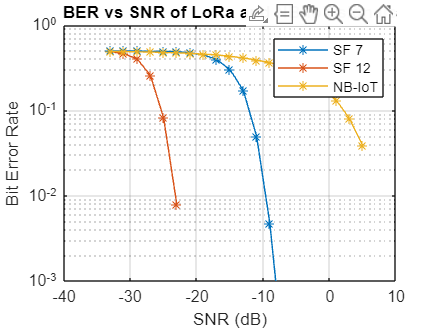

% lora_ber10=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    theoryBer12=qfunc((log(12)/log(12))/sqrt(2)*(SNRvec+10*log10((2^12)/12)));
    
    theoryBer7=-0.5+qfunc((log(7)/log(12))/sqrt(2)*(SNRvec+10*log10((2^7)/7)));
    % semilogy(SNRvec',theoryBer12,'-*')
    % hold on
    % semilogy(SNRvec',theoryBer7,'-*')
    %hold on
    semilogy(SNRvec',lora_ber7,'-*')
    hold on
    %semilogy(SNRvec',lora_ber10,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    semilogy(SNRvec',nbiot_ber,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-4 1])
    %legend('theory 12','theory 7','SF 7','SF 9','SF 12')%adjust legend!
    legend( 'SF 7','SF 12','NB-IoT')
    title('BER vs SNR of LoRa and NB-IoT signals')
    
end


%% compare with nbiot


## doppler corection

shifting the signal with n kHz will shift the demodulated symbol with (dopplerShift/BW)*SF

e.g. with SF=7, symbol 0 will be demodulated as 66 when the signal is shifted with 64 kHz 

original symbol = received symbol -(dopplerShift/125kHz)*SF)

to estimate frequency shift: ((receivedSymbol-expectedSymbol)/SF)*BW